老师的代码使用

对于type 2或以上的系统，一定会产生overshoot


$$P\left(s\right)=\frac{2s+10}{s^2 \left(s+1\right)}$$


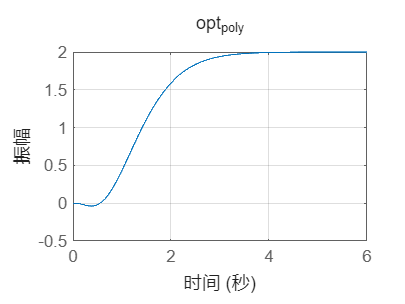

clf; clear;
denum = [1,1,0,0];
num = [2 -10];
Plant = tf(num,denum);
Q2 = opt_poly(Plant);
[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = (Plant*C1)/(1+Plant*C2);
step(T)
title("opt_{poly}");
grid on;

我的代码使用

clf; clear;
denum = [1,1,0,0];
num = [2 -10];
Plant = tf(num,denum);
Q2=TwoDOFFeedbackTuningFunction(num,denum);
[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = (Plant*C1)/(1+Plant*C2);
step(T)
title("mine")
grid on;